M =     0.0193    0.0112    0.0072


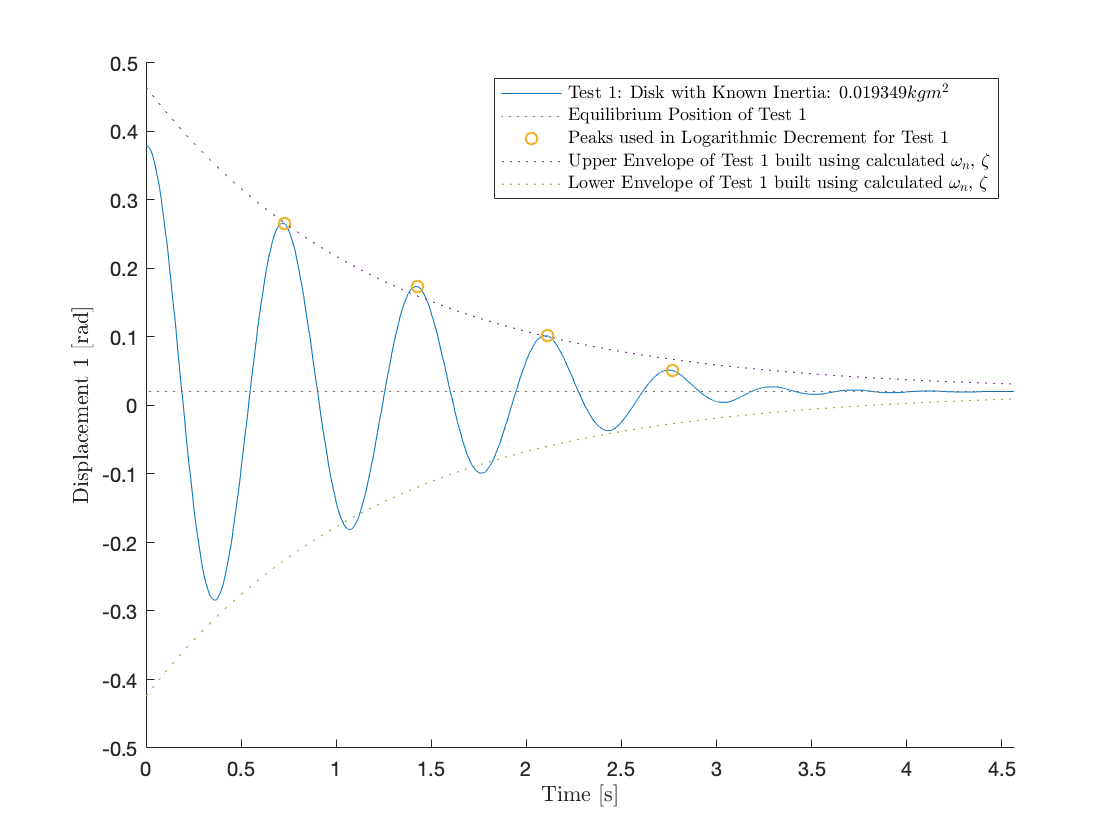

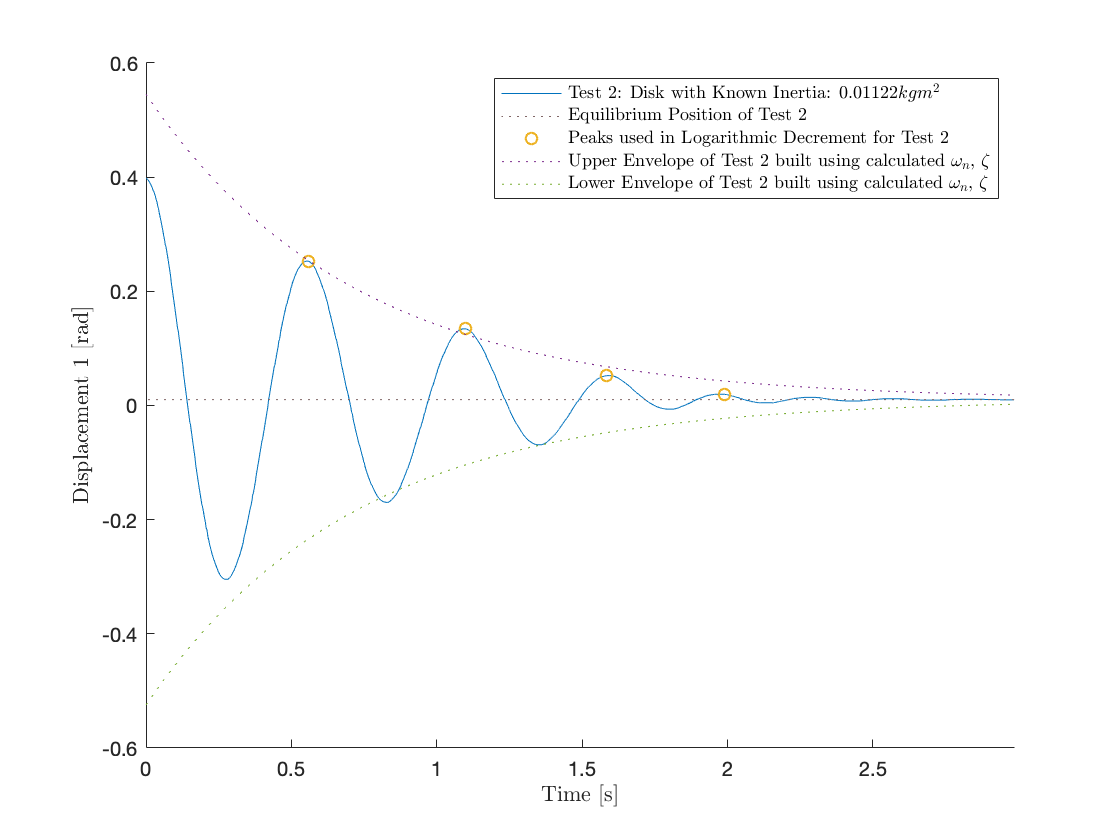

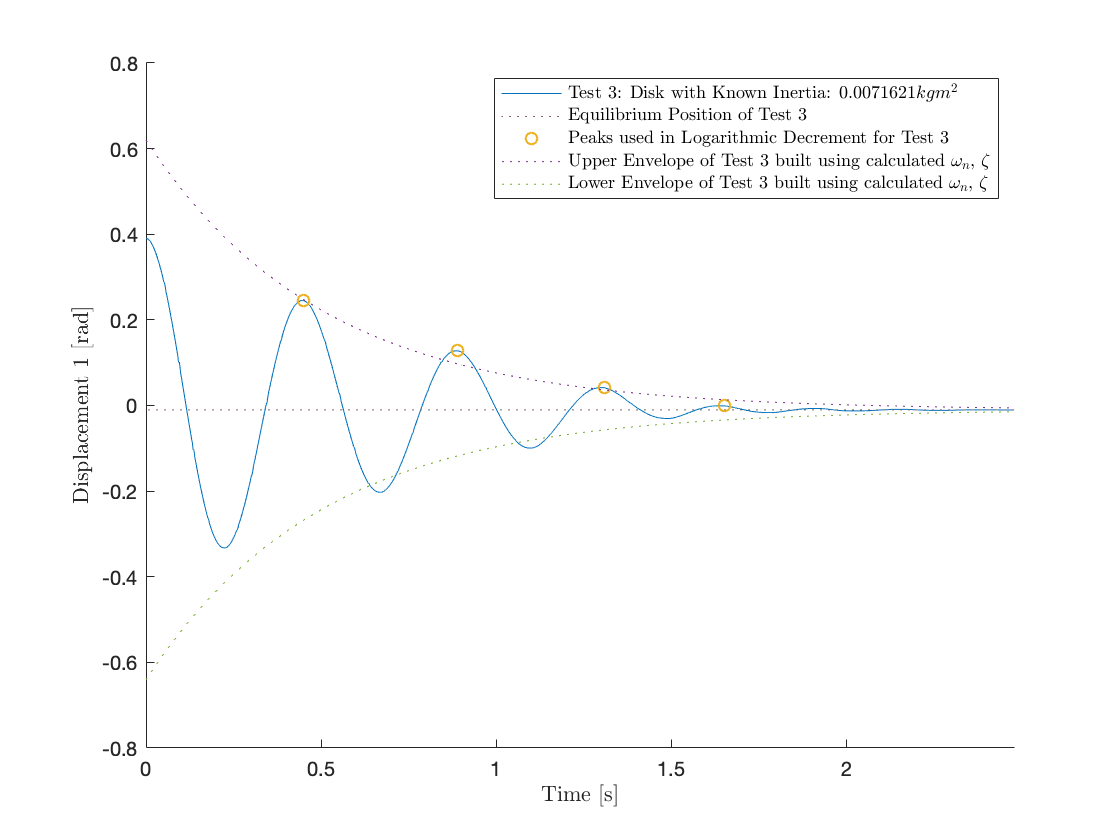

    "wn: 9.27562"    "wn: 13.2379"    "wn: 15.8074"

    "z: 0.087576"    "z: 0.10615"    "z: 0.12582"



k =     1.6647    1.9663    1.7896


b =     0.0314    0.0315    0.0285


ans = 1.8069

ans = 0.0305

rot_q5_run()

function rot_q5_run()
    % PRIOR KNOWNS:
    % Masses of Blocks [kg]:
    mb1 = 501.5e-3;
    mb2 = 501e-3;
    mb3 = 501.25e-3;
    mb4 = 502.25e-3;
    
    Jdisk = 0.0031; % Inertia of Disk  Determined in Lab 1
    
    % Known Mass added to Each Disk [kg]:
    m1 = mb1 + mb2 + mb3 + mb4; % Known mass added to disk in experiment 1
    m2 = mb1 + mb2; % Known mass added to disk in experiment 2
    m3 = mb1; % Known mass added to disk in experiment 2
    J1 = m1*(9e-2)^2;
    J2 = m2*(9e-2)^2;
    J3 = m3*(9e-2)^2;
    
    % Known Inertias for Each Experiment:
    M(1) = Jdisk + J1;
    M(2) = Jdisk + J2;
    M(3) = Jdisk + J3
    
    % Perform Logarithmic Decrement on All Experiments:
    for i = 1:3
        [wn(i), z(i), ~, ~, t_end] = multi_logdec("rad", "RotData/exp2/2.1/", i, "test"+i, M(i)+"$kgm^{2}$");
        xlim([0 t_end(1)])
        saveas(gcf, char("Rot_q5-"+i+".png"), 'png');
    end
    %Display Logarithmic Decrement Results:
    disp("wn: " + wn);
    disp("z: " + z);
    
    % Compute All Unknowns:
    k = wn.^2 .* M
    b = 2 .* z .* wn .* M
    mean(k)
    mean(b)
end